# segmentation_snooper

View forceplate data along with 0 crossing, stride segmentation, and swingstance locations

Instructions for use:

        1) Create breakpoint after segmentation snooper comment block in GRFsegment_full.mlx

        2) Run viconExtract_VAII.mlx. Program will stop at the set breakpoint

        2) Save workspace as snoopdata.mat

        3) Stop viconExtract and run this program

**Troubleshooting**

Guide on how to adjust `threshold` in `GRFsegment_full.mlx based on graph`

    Example of good segmentation:

            Characteristics: No points during stance phase (high forceplate readings)

                                      Consistent labelling of start/end of stance

                                      Very few outliers (will be removed by z-score outlier removal)

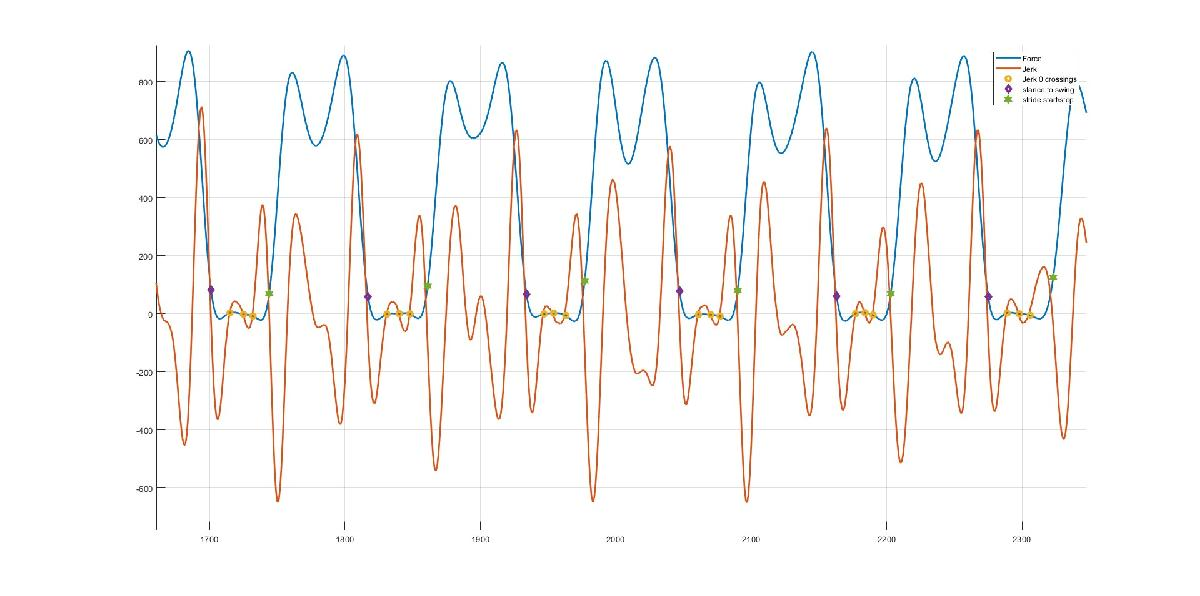

    Bad Segmentation: Threshold too high

        Characteristics: points captured during stance (high forceplate readings)

        Solution: Lower threshold

        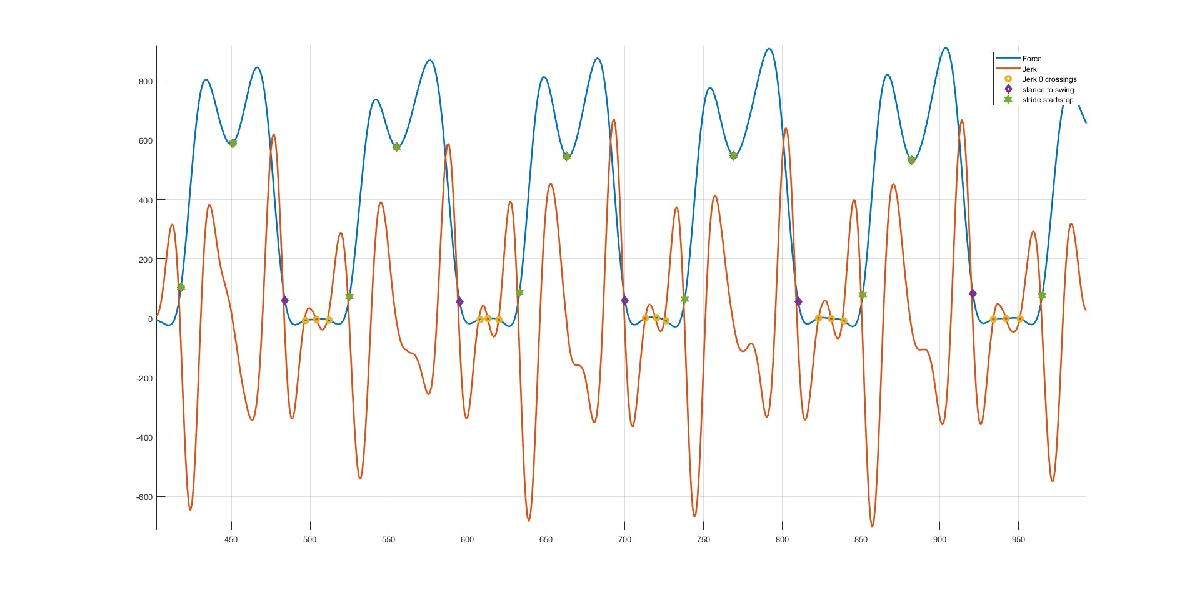

    Bad Segmentation: Threshold too low

            Characteristics: inconsistent/nonexistent segmentation points

            Solution: Raise threshold

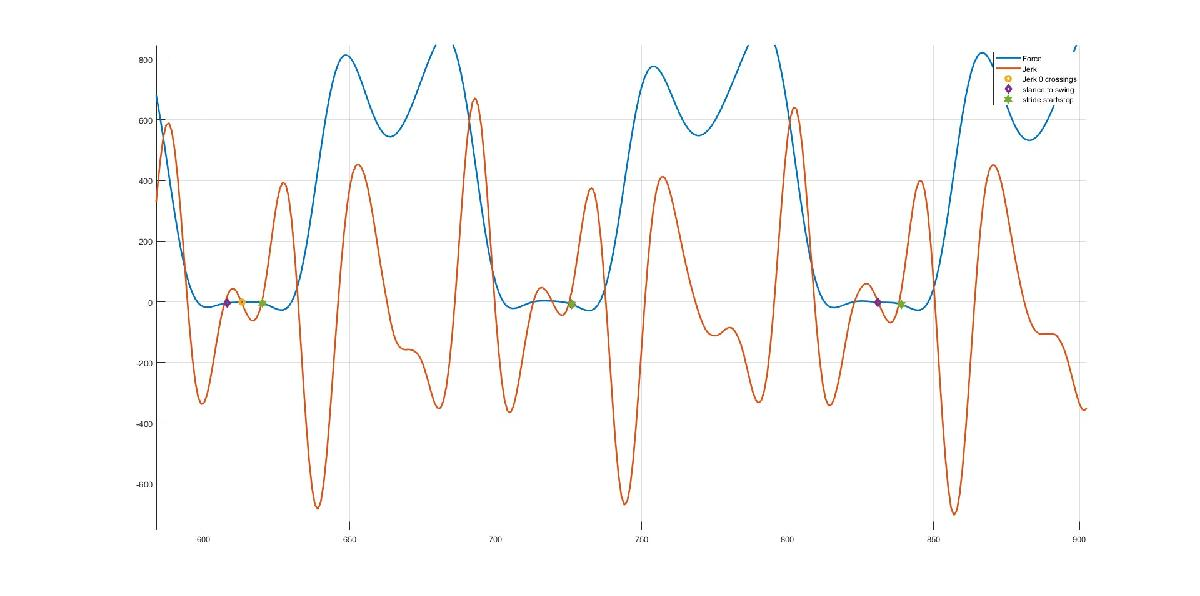

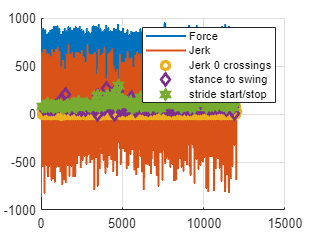

addpath(genpath(pwd))
load("snoopdata.mat")

range_min = 1;
range_max = length(filtered_fp);

figure("Name", "Stride Segmentation")
hold on, grid on, legend()
plot(range_min:range_max, filtered_fp(range_min:range_max), 'DisplayName', "Force", "LineWidth", 1.5)
plot(range_min:range_max, jerk_y(range_min:range_max)*2e-4, 'DisplayName', "Jerk", "LineWidth", 1.5)

crossings = fod_0_cross(abs(fod_0_cross - (range_min + range_max)/2.) < (range_max - range_min)/2.);
swingstance = fod_swingstance(abs(fod_swingstance - (range_min + range_max)/2.) < (range_max - range_min)/2.);
segments = fod_segments(abs(fod_segments - (range_min + range_max)/2.) < (range_max - range_min)/2.);

crossings = setxor(setxor(crossings, swingstance), segments);

scatter(crossings, filtered_fp(crossings), "Marker", "o", "LineWidth", 2.5, 'DisplayName', "Jerk 0 crossings")
scatter(swingstance, filtered_fp(swingstance), "Marker", "diamond", "LineWidth", 2.5, 'DisplayName', "stance to swing")
scatter(segments, filtered_fp(segments), "Marker","hexagram", "LineWidth", 2.5, 'DisplayName', "stride start/stop")

% Z-score outlier removal demo
swingstance_lengths = abs(fod_strides - horzcat(fod_swingstance' , fod_swingstance'));
vars = var(swingstance_lengths)

vars =    84.5288   93.6011


means = mean(swingstance_lengths, 1)

means =    71.9905   40.2286



[n, ~] = size(swingstance_lengths);
stride_zscore = ((swingstance_lengths - repmat(means, n, 1))) .* repmat(1./sqrt(vars), n, 1);
accepted_strides = abs(stride_zscore(:, 1)) + abs(stride_zscore(:, 2)) < zscore_max;
good_strides = fod_strides(accepted_strides, :);

good_ranges = [];
for s = 1:length(good_strides(:, 1))
    good_ranges = [good_ranges, good_strides(s, 1):good_strides(s, 2)-1];
end

figure("Name", "Z-score Outlier Removal")
hold on, grid on, legend()
plot(1:length(good_ranges), filtered_fp(good_ranges), 'DisplayName', "Force", "LineWidth", 1.5)
plot(1:length(good_ranges), jerk_y(good_ranges)*2e-4, 'DisplayName', "Jerk", "LineWidth", 1.5)

crossings_good = [];
for i = 1:length(crossings)
    crossings_good = [crossings_good, find(good_ranges == crossings(i))];
end

swingstance_good = [];
for i = 1:length(swingstance)
    swingstance_good = [swingstance_good, find(good_ranges == swingstance(i))];
end

segments_good = [];
for i = 1:length(segments)
    segments_good = [segments_good, find(good_ranges == segments(i))];
end

filtered_fp_good = filtered_fp(good_ranges)

filtered_fp_good =    75.0189  110.8089  152.7702  200.3009  252.4660  308.0444  365.5952  423.5398  480.2557  534.1637  583.8308  628.0431  665.8708  696.7026  720.2613  736.5926  746.0406  749.1859  746.8036  739.7989  729.1519  715.8506  700.8399  684.9889  669.0697  653.7483  639.5831  627.0431  616.4873  608.2022  602.3974  599.2229  598.7896  601.1529  606.3193  614.2503  624.8542  637.9936  653.4810  671.0810  690.5189  711.4608  733.5111  756.2292  779.1105  801.5911  823.0202  842.6433  859.6173  873.0165


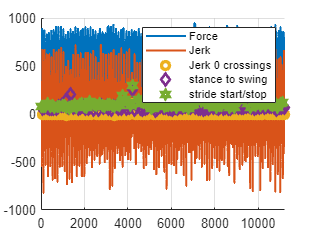


scatter(crossings_good, filtered_fp_good(crossings_good), "Marker", "o", "LineWidth", 2.5, 'DisplayName', "Jerk 0 crossings")
scatter(swingstance_good, filtered_fp_good(swingstance_good), "Marker", "diamond", "LineWidth", 2.5, 'DisplayName', "stance to swing")
scatter(segments_good, filtered_fp_good(segments_good), "Marker","hexagram", "LineWidth", 2.5, 'DisplayName', "stride start/stop")